需修改输入参数和输出文件名；同时需注意寻峰位置是否正确。

# 输入

## 文件夹地址

读取同一个电池不同扫描速度的CV图

% 设定数据文件夹路径
folderPath = 'G:\Study Doc\matlab\CV';

% 检查文件夹是否存在
if ~isfolder(folderPath)
    error('指定的文件夹路径不存在: %s', folderPath);
end

% 获取文件夹中所有的 Excel 文件
fileNames = dir(fullfile(folderPath, '*.xlsx'));

if isempty(fileNames)
    disp('该文件夹中没有 Excel 文件');
    return;
end

## 输入公式参数

%扫描速度，矩阵，有几个文件夹就有几个数值(mV*s^-1)
v=[0.1];
%转移电子数
n=1;
%电极面积cm^2
A=1.131;
%锂离子mol浓度（mol*cm^-3）
C=0.0228;

# 绘不同扫描速度CV图

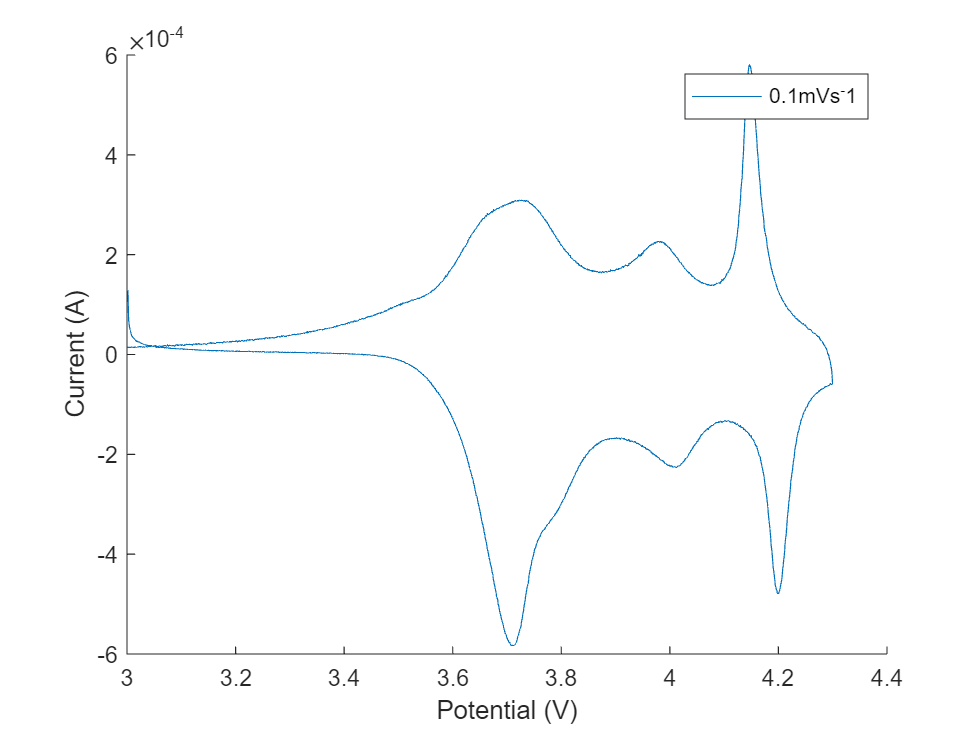

figure;

% 预分配图例条目
legendEntries = cell(length(fileNames), 1); 

% 循环读取文件和绘图
hold on; % 一次性设置 hold on

% 读取文件夹中的每个 Excel 文件并绘制图像
for i = 1:length(fileNames)
    % 获取文件名（去除.xlsx后缀）
    [~, fileName, ~] = fileparts(fileNames(i).name);
    
    % 读取Excel文件的数据
    filePath = fullfile(folderPath, fileNames(i).name);
    data = readmatrix(filePath); % 读取Excel文件中的所有数据
   
    % 绘制散点图
    x = data(:, 1);
    y = data(:, 2);
    plot(x,y);
   
    % 为每个文件生成图例条目
    legendEntries{i} = fileName;
end

legend(legendEntries);

% 在循环外设置 hold off
hold off; 

% 设置标签
xlabel('Potential (V)');
ylabel('Current (A)');

# 找到Ip

%设置初始值
pks1=[];
pks2=[];
Ip=[];

% 读取文件夹中的每个 Excel 文件并绘制图像
for i = 1:length(fileNames)
    % 获取文件名（去除.xlsx后缀）
    [~, fileName, ~] = fileparts(fileNames(i).name);
    
    % 读取Excel文件的数据
    filePath = fullfile(fileNames(i).name);
    data = readmatrix(filePath); % 读取Excel文件中的所有数据

    x = data(:, 1);
    y = data(:, 2);

    %找到正负值分界点
    index = find (x==max(x));
    %对前半段充电过程x按照升序排序
    [x1,I1] = sort(x(1:index));
    %对y按照x的位置排序并取反
    y1 = -y(I1);

    %后半段放电过程重复操作
    [x2,I2] = sort(x(1+index:end));
    y2 = y(index+I2);
    

检查寻峰位置是否正确，可能需要更改高斯滤波器参数或寻峰参数

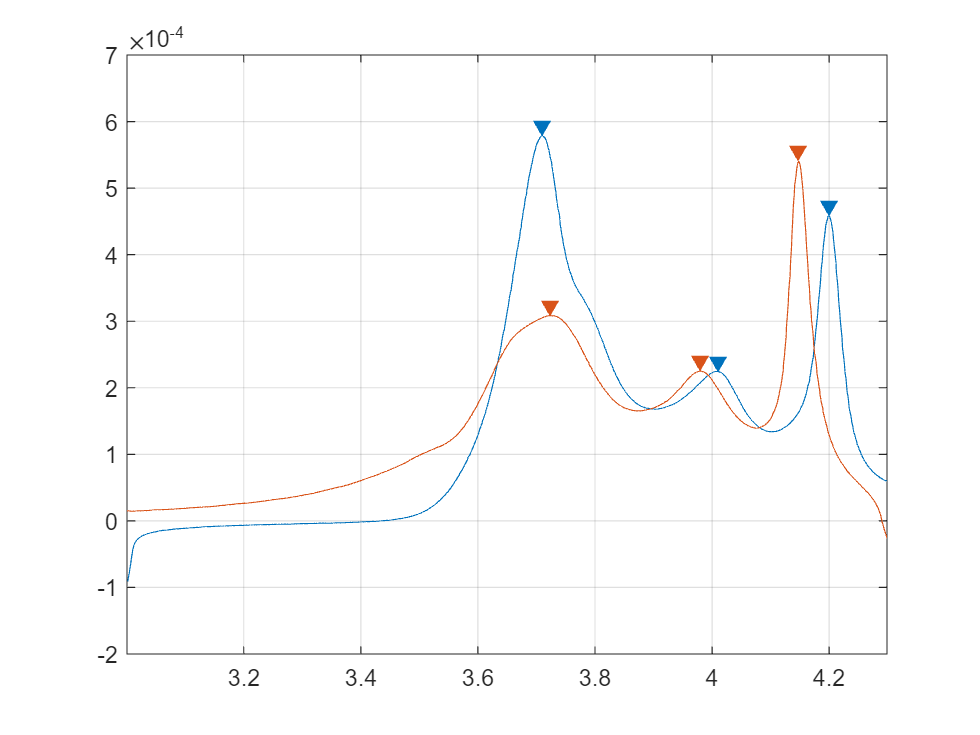

     % 创建高斯滤波器
    sigma = 15;
    gaussian_filter = fspecial('gaussian', [15, 15], sigma);
    % 应用高斯滤波器进行平滑
    smoothed_y1 = imfilter(y1, gaussian_filter, 'replicate');
    smoothed_y2 = imfilter(y2, gaussian_filter, 'replicate');

    %寻峰
    findpeaks(smoothed_y1,x1,'MinPeakDistance',0.1,'MinPeakHeight',0.0002);%充电
    hold on;
    findpeaks(smoothed_y2,x2,'MinPeakDistance',0.1,'MinPeakHeight',0.0002);%放电
    hold off;

    pk1=findpeaks(smoothed_y1,x1,'MinPeakDistance',0.1,'MinPeakHeight',0.0002);%充电
    pk2=findpeaks(smoothed_y2,x2,'MinPeakDistance',0.1,'MinPeakHeight',0.0002);%放电
    %化成行向量，并实现不同扫描速度的数据合并
    pks1=[pks1,pk1'];
    pks2=[pks2,pk2'];
end

%化成列向量

Ip = 1.0e-03 *

    0.5785    0.3082
    0.2244    0.2250
    0.4581    0.5400


pks1=pks1';%充电
pks2=-pks2';%放电,为负值

# 画Ip和v^0.5

a=v^0.5;
b=pks1;
c=pks2;

%画散点图
scatter(a,b);%充电
hold on;
scatter(a,c);%放电
hold off;

线性拟合部分（看是否需要）

% % 线性拟合
% p1 = polyfit(a, b, 1);  % 一次拟合，p(1) 为斜率 k，p(2) 为截距 b
% k1 = p(1);  % 斜率
% p2 = polyfit(a, c, 1);  % 一次拟合，p(1) 为斜率 k，p(2) 为截距 b
% k2 = p(1);  % 斜率
% 
% %计算扩散系数
% D1=(k1/2.69/10^5*n^(2/3)/C)^2
% D2=(k2/2.69/10^5*n^(2/3)/C)^2

# 输出文件名设置

writematrix(v^0.5 pks1 pks2,'电池编号-v^0.5-充放电Ip.txt', 'Delimiter', 'tab');